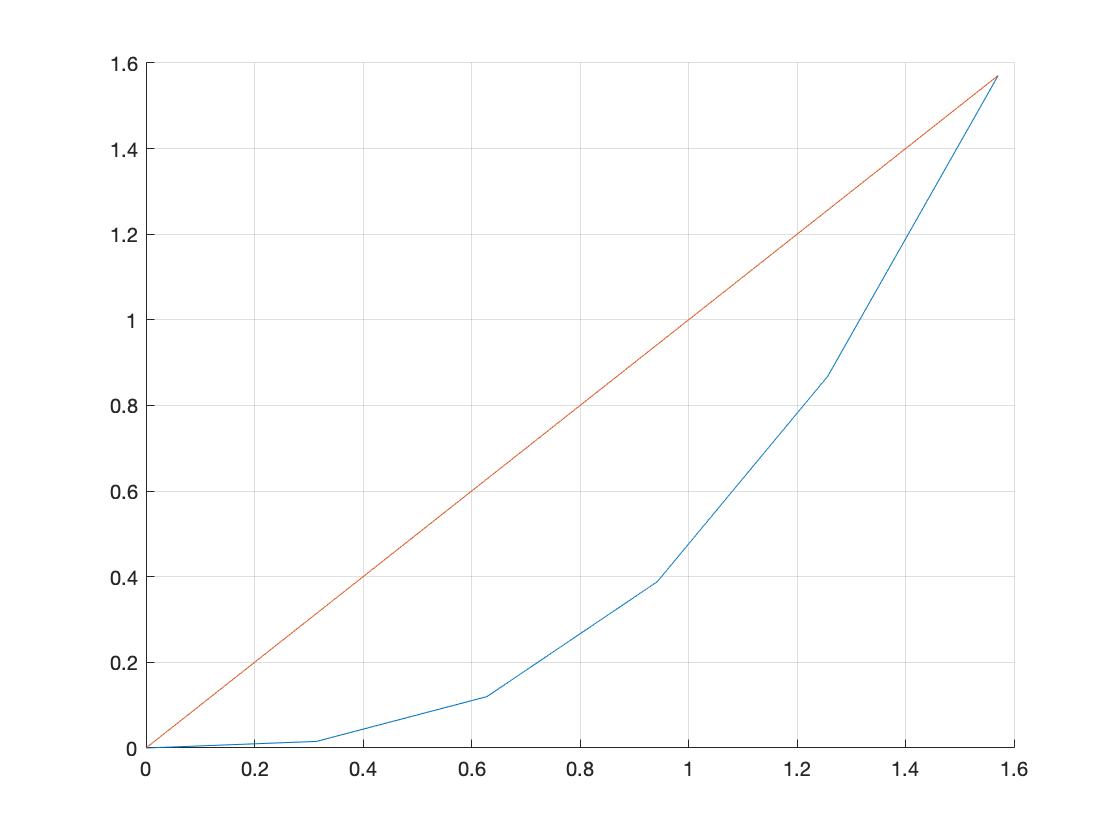

xjs = [0:5].*pi./10; % training points
g = @(x) 1-cos(x); % ground truth
yjs = g(xjs);
relu = @(w)max(w,0);
drelu = @(w)ones(size(w)).*sign(relu(w));
A = [xjs' -1.*ones(length(xjs),1)];
[As,Bs] = meshgrid(-1:0.1:1);
ffun = @(a,b,c,d) f(a,b,c,d);
grada_fun = @(a,b,c,d) grad_a(a,b,c,d);
gradb_fun = @(a,b,c,d) grad_b(a,b,c,d);

grad_a(1,0,xjs,yjs)

ans = 0.4109

grad_b(1,0,xjs,yjs)

ans = -0.2916

nsteps=800000;
[a,b,fs,gs,ags,bgs]=GD(1,0,ffun,grada_fun,gradb_fun,xjs,yjs,'constant',nsteps);
a

a = 0.4948

b

b = -0.0855

fs(end)

ans = 0.0104

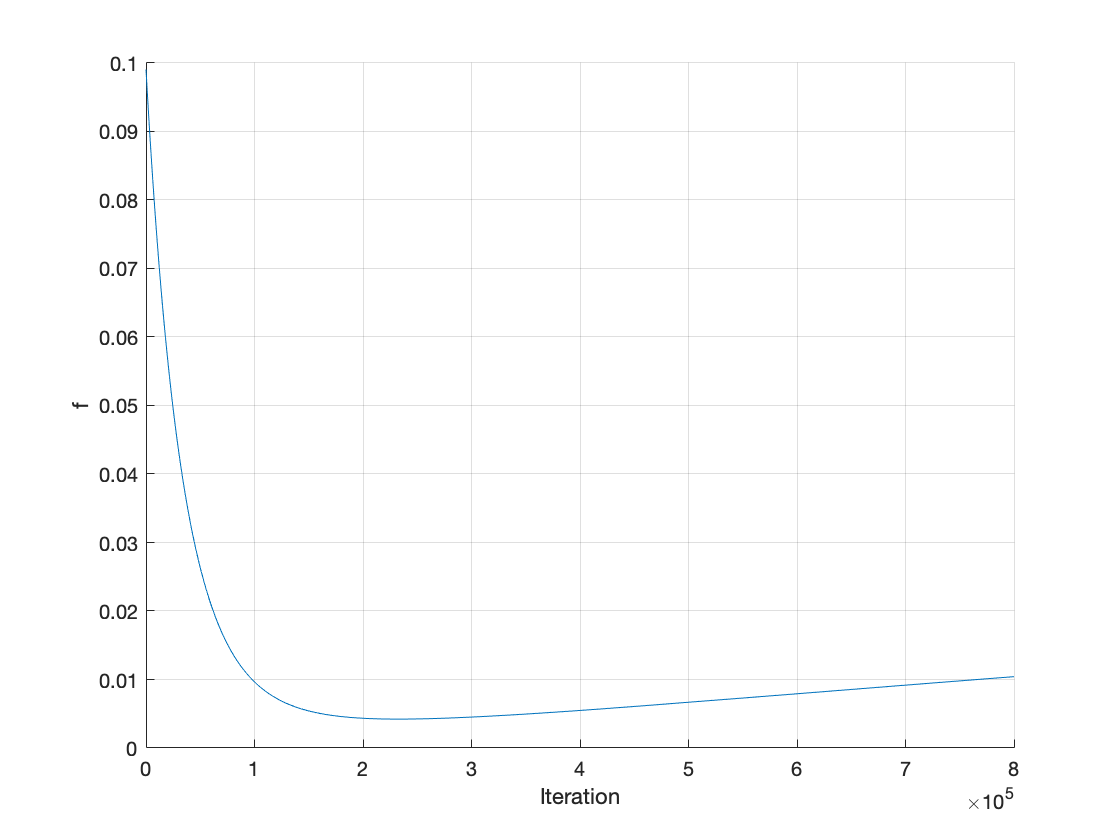

figure;
grid on; hold on;
plot(1:length(fs),fs);
xlabel('Iteration'); ylabel('f');
saveas(gcf,'figures/gdconst_f.png');

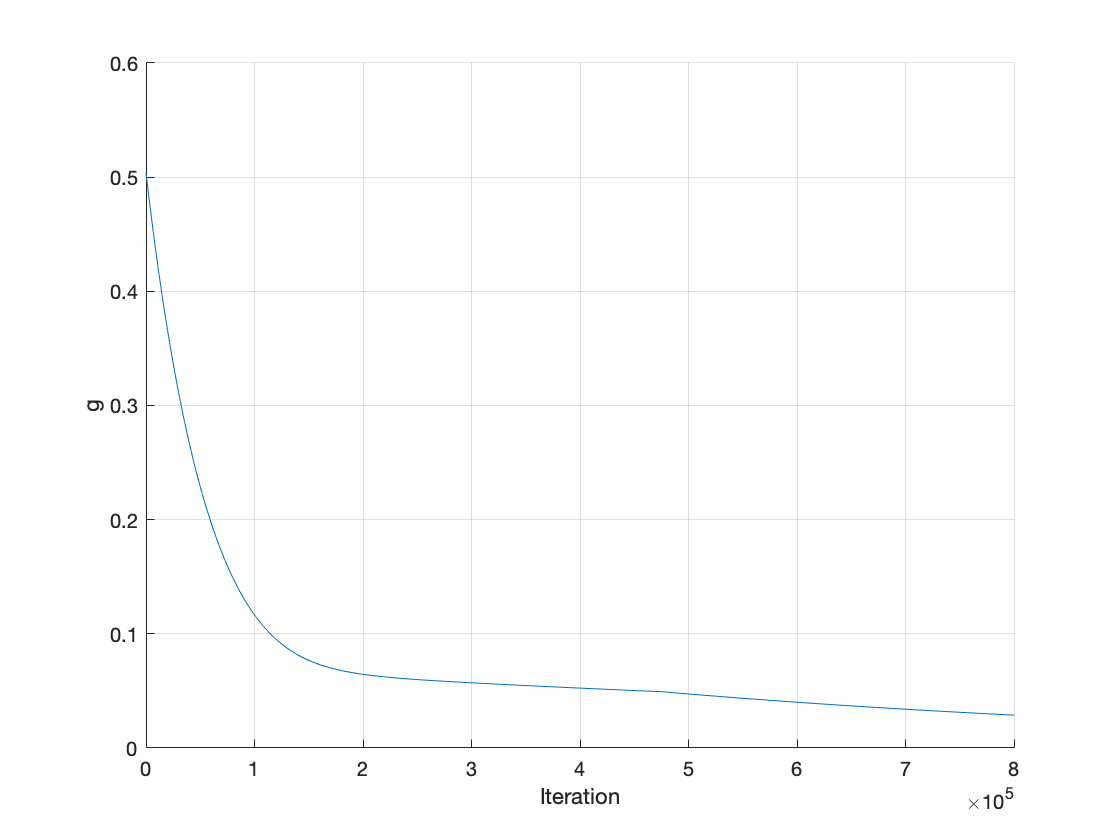

figure;
grid on; hold on;
plot(1:length(gs),gs);
xlabel('Iteration'); ylabel('g');
saveas(gcf,'figures/gdconst_g.png');

(1-0.86)/grad_a(1,0,xjs,yjs)

ans = 0.3407

(0-0.37)/grad_b(1,0,xjs,yjs)

ans = 1.2690